# Изучение красного смещения

close all
clear variables

## **Импорт данных**

spectra = importdata("lab_1\data\spectra.csv")

spectra = 1.0e-12 *

    0.3088    0.1340    0.0598    0.0892    0.1088    0.1625    0.0392
    0.3136    0.1338    0.0607    0.0898    0.1084    0.1630    0.0382
    0.3105    0.1347    0.0618    0.0915    0.1104    0.1615    0.0371
    0.3076    0.1357    0.0625    0.0931    0.1124    0.1586    0.0378
    0.3088    0.1354    0.0627    0.0936    0.1122    0.1574    0.0391
    0.3105    0.1343    0.0622    0.0932    0.1136    0.1589    0.0396
    0.3122    0.1335    0.0619    0.0929    0.1138    0.1611    0.0402
    0.3101    0.1325    0.0620    0.0925    0.1130    0.1607    0.0399
    0.3078    0.1335    0.0626    0.0924    0.1124    0.1593    0.0387
    0.3047    0.1329    0.0625    0.0918    0.1108    0.1582    0.0379


lambdaStart = importdata("lab_1\data\lambda_start.csv")

lambdaStart = 630.0200

lamdaDelta = importdata("lab_1\data\lambda_delta.csv")

lamdaDelta = 0.1400

starNames = importdata("lab_1\data\star_names.csv")

starNames = 7×1 cell array
    {'HD30584'  }
    {'HD10032'  }
    {'HD64191'  }
    {'HD5211'   }
    {'HD56030'  }
    {'HD94028'  }
    {'SAO102986'}


## **Константы**

lamdaHa0 = 656.28

lamdaHa0 = 656.2800

c = 299792.458

c = 2.9979e+05

`где lamdaHa0 -- `реальная длины волны линии *Бальмер-Альфа в нм*

`    c` -- скорость света в вакууме в $\frac{\textrm{км}}{с}$

## **Определение числа наблюдений и количества исследуемых звёзд**

num_obs = size(spectra, 1)

num_obs = 357

num_stars = size(starNames, 1)

num_stars = 7

## **Определение диапазона длин волн**

lambdaEnd = lambdaStart + (num_obs - 1) * lamdaDelta

lambdaEnd = 679.8600

lamda = (lambdaStart : lamdaDelta : lambdaEnd)

lamda =   630.0200  630.1600  630.3000  630.4400  630.5800  630.7200  630.8600  631.0000  631.1400  631.2800  631.4200  631.5600  631.7000  631.8400  631.9800  632.1200  632.2600  632.4000  632.5400  632.6800  632.8200  632.9600  633.1000  633.2400  633.3800  633.5200  633.6600  633.8000  633.9400  634.0800  634.2200  634.3600  634.5000  634.6400  634.7800  634.9200  635.0600  635.2000  635.3400  635.4800  635.6200  635.7600  635.9000  636.0400  636.1800  636.3200  636.4600  636.6000  636.7400  636.8800


## **Получение минимальных интенсивностей и их индексов для всех звезд**

[sHa, idx] = min(spectra)

sHa = 1.0e-12 *

    0.1634    0.0724    0.0314    0.0536    0.0690    0.0980    0.0221


idx =    188   187   188   189   189   191   185


## Расчет скорости движения звёзд

Рассчёт скорости производится на основании наблюдаемого спектрального поглощения. В нём минимум интесивности располагается на наблюдаемой длине волны линии *Бальмера-Альфа* (`lambaHa`). Поскольку звезда либо удаляется, либо приближается к наблюдателю, то наблюдаемая линия будет сдвинута для наблюдателя в большую или меньшую сторону относительно реальной длины волны линии *Бальмер-Альфа* (`lambdaHa0`).

Относительное изменение длины волны, которое рассчитывается по формуле:


$$Z=\frac{\textrm{lambda}}{\textrm{lambda0}}-1$$
 

называется красным смещением. Исходя из значения красного смещения можно выразить скорость звезды по формуле:


$$\textrm{Vstar}=Z*c$$


lamdaHa = lamda(idx)

lamdaHa =   656.2000  656.0600  656.2000  656.3400  656.3400  656.6200  655.7800


Z = (lamdaHa / lamdaHa0) - 1

Z = 1.0e-03 *

   -0.1219   -0.3352   -0.1219    0.0914    0.0914    0.5181   -0.7619


speed = Z * c

speed =   -36.5445 -100.4973  -36.5445   27.4083   27.4083  155.3139 -228.4029


## Построение графика

fg = figure

fg =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 378 560 420]
       Units: 'pixels'

  Show all properties


set(fg, "Visible", "on")
xlabel('Длина волны, нм')
ylabel(['Интенсивность, эрг/см^2/c/0', char(197)])
title({'Спектр звёзд'})
grid on
grid minor
hold all
for i = 1:num_stars
    if Z(i) < 0
        plot(lamda, spectra(:, i), '--', 'LineWidth', 1)
    else
        plot(lamda, spectra(:, i), 'LineWidth', 3)
    end
end
xline(lamdaHa0, 'r--', 'LineWidth', 3)
legend(starNames)
t = text(lamdaHa0 + 0.5, max(max(spectra)), 'H\alpha', 'Color', 'red')

t =   Text (H\alpha) with properties:

                 String: 'H\alpha'
               FontSize: 10
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [1 0 0]
    HorizontalAlignment: 'left'
               Position: [656.7800 3.1360e-13 0]
                  Units: 'data'

  Show all properties


t.Rotation = 90

t =   Text (H\alpha) with properties:

                 String: 'H\alpha'
               FontSize: 10
             FontWeight: 'normal'
               FontName: 'Helvetica'
                  Color: [1 0 0]
    HorizontalAlignment: 'left'
               Position: [656.7800 3.1360e-13 0]
                  Units: 'data'

  Show all properties


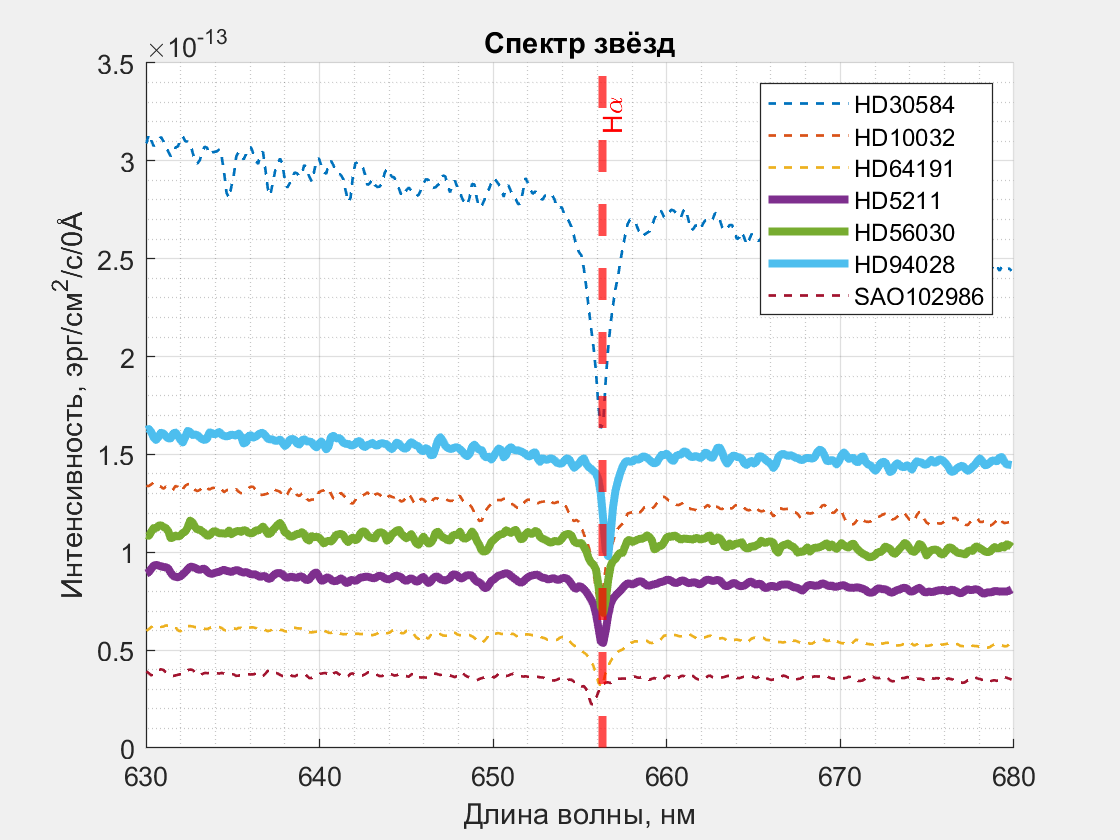

hold off

## Получение вектора с именами звёзд, которые удаляются

Для получение имен звёзд, которые удаляются необходимо, чтобы значение их красного смещения было отрицательным.

movaway = starNames(Z < 0)

movaway = 4×1 cell array
    {'HD30584'  }
    {'HD10032'  }
    {'HD64191'  }
    {'SAO102986'}


## Сохранение графика

saveas(fg, 'lab_1\star_spectr.png')